clc
clear all
% OFDM system parameters
Nc = 100;        % Number of OFDM blocks
Td = 32;          % IFFT size
Tc = 8;       % Cyclic prefix size
N = Td * Nc;

% Modulation parameters
M = 16;                 % QAM order

% SNR value
EbNo = -10;             % SNR value in dB

% Varying Pfa values
Pfa = 0:0.001:1;

% Initialize arrays for Pd (probability of detection)
Pd = zeros(size(Pfa));

% Generate random binary data
data = randi([0, 1], N * log2(M), 1);

% Reshape binary data into symbols
dataSymbols = reshape(data, log2(M), []).';

% Map bits to constellation points
constellation = qammod(0:M-1, M);
modulatedSymbols = constellation(bin2dec(num2str(dataSymbols))+1);

% Reshape modulated symbols into blocks
modulatedSymbols = reshape(modulatedSymbols, Td, Nc);

% Perform IFFT on each block
timeDomainSignal = ifft(modulatedSymbols, Td);

% Add cyclic prefix
timeDomainSignalWithCP = [timeDomainSignal(end-Tc+1:end, :); timeDomainSignal];

% Convert time-domain signal to serial stream
transmittedSignal = timeDomainSignalWithCP(:);

% Add AWGN noise to the transmitted signal
snr = 10^(EbNo/10);                           % Convert EbNo from dB to linear scale
noiseVar = 1/(2*snr);                         % Calculate noise variance

% Calculate detection threshold based on Pfa
rho1 = (Tc)/(Td+Tc)*(snr)/(1+snr);
threshold = 2*qfuncinv(Pfa) * sqrt(2 * noiseVar)+3.3;
%threshold = 1/sqrt(3200).*erfcinv(2.*Pfa)
%threshold = (1-rho1^2)/(2*M*rho1) * (M*log(1-rho1^2))  + rho1
% Simulate the OFDM system for each Pfa value
for i = 1:length(Pfa)
    noise = sqrt(noiseVar/2) * (randn(size(transmittedSignal)) + 1i * randn(size(transmittedSignal)));
    receivedSignal = transmittedSignal + noise;

    % Reshape received signal into blocks with cyclic prefix
    receivedSignalWithCP = reshape(receivedSignal, Td+Tc, []);

    % Remove cyclic prefix
    receivedSignal = receivedSignalWithCP(Tc+1:end, :);

    % Perform FFT on each block
    receivedSymbols = fft(receivedSignal, Td);

    % Reshape received symbols into a serial stream
    receivedSymbols = receivedSymbols(:);

    % Calculate probability of detection (Pd)
    detections = sum(abs(receivedSymbols) > threshold(i));
    Pd(i) = detections / N;
end

k = 4

Pfasim =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



% Plot the ROC curve
figure;
plot(Pfa, Pd);
xlabel('Probability of False Alarm (Pfa)');
ylabel('Probability of Detection (Pd)');
title(['Receiver Operating Characteristic (ROC) Curve for OFDM System at SNR = ' num2str(EbNo) ' dB']);
grid on;

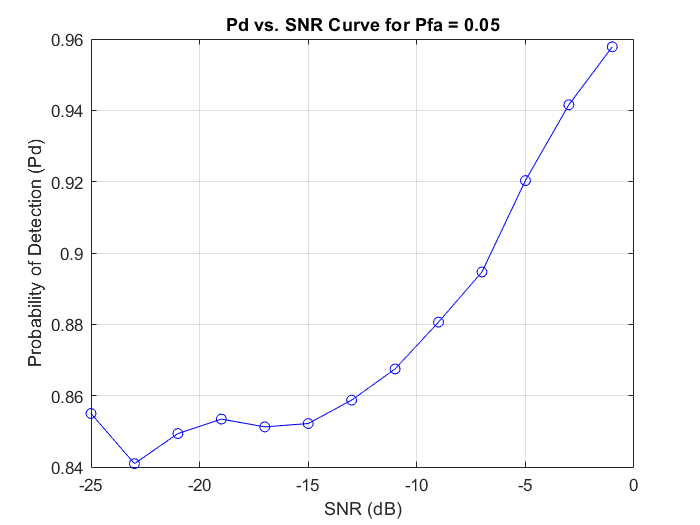

clear all
% OFDM system parameters
numBlocks = 100;        % Number of OFDM blocks
IFFTSize = 32;          % IFFT size
cyclicPrefix = 8;       % Cyclic prefix size
numSymbols = IFFTSize * numBlocks;

% Modulation parameters
M = 16;                 % QAM order

% Varying SNR values
EbNo_dB = -25:2:0;     % Range of SNR values in dB
EbNo = 10.^(EbNo_dB/10);% Convert SNR from dB to linear scale

% Fixed Pfa value
Pfa = 0.05;

% Initialize arrays for Pd (probability of detection)
Pd = zeros(size(EbNo_dB));

% Generate random binary data
data = randi([0, 1], numSymbols * log2(M), 1);

% Reshape binary data into symbols
dataSymbols = reshape(data, log2(M), []).';

% Map bits to constellation points
constellation = qammod(0:M-1, M);
modulatedSymbols = constellation(bin2dec(num2str(dataSymbols))+1);

% Reshape modulated symbols into blocks
modulatedSymbols = reshape(modulatedSymbols, IFFTSize, numBlocks);

% Perform IFFT on each block
timeDomainSignal = ifft(modulatedSymbols, IFFTSize);

% Add cyclic prefix
timeDomainSignalWithCP = [timeDomainSignal(end-cyclicPrefix+1:end, :); timeDomainSignal];

% Convert time-domain signal to serial stream
transmittedSignal = timeDomainSignalWithCP(:);

% Simulate the OFDM system for each SNR value
for i = 1:length(EbNo_dB)
    % Add AWGN noise to the transmitted signal
    noiseVar = 1 / (2 * EbNo(i) * log2(M));  % Calculate noise variance
    noise = sqrt(noiseVar/2) * (randn(size(transmittedSignal)) + 1i * randn(size(transmittedSignal)));
    receivedSignal = transmittedSignal + noise;

    % Reshape received signal into blocks with cyclic prefix
    receivedSignalWithCP = reshape(receivedSignal, IFFTSize+cyclicPrefix, []);

    % Remove cyclic prefix
    receivedSignal = receivedSignalWithCP(cyclicPrefix+1:end, :);

    % Perform FFT on each block
    receivedSymbols = fft(receivedSignal, IFFTSize);

    % Reshape received symbols into a serial stream
    receivedSymbols = receivedSymbols(:);

    % Calculate detection threshold based on Pfa
    threshold = qfuncinv(Pfa) * sqrt(2 * noiseVar);

    % Calculate probability of detection (Pd)
    detections = sum(abs(receivedSymbols) > threshold);
    Pd(i) = detections / numSymbols;
end

% Plot the Pd vs. SNR curve
figure;
plot(EbNo_dB, Pd, 'b-o');
xlabel('SNR (dB)');
ylabel('Probability of Detection (Pd)');
title(['Pd vs. SNR Curve for Pfa = ' num2str(Pfa)]);
grid on;

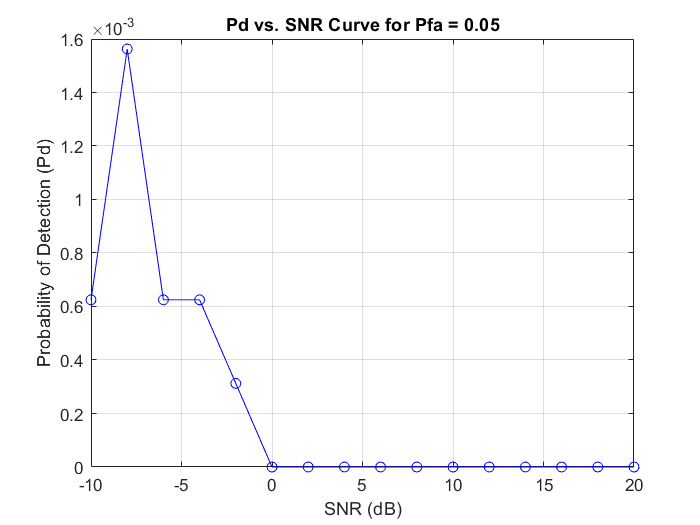

% OFDM system parameters
numBlocks = 100;        % Number of OFDM blocks
IFFTSize = 32;          % IFFT size
numSymbols = IFFTSize * numBlocks;

% Modulation parameters
M = 16;                 % QAM order

% Varying SNR values
EbNo_dB = -10:2:20;     % Range of SNR values in dB
EbNo = 10.^(EbNo_dB/10);% Convert SNR from dB to linear scale

% Fixed Pfa value
Pfa = 0.05;

% Initialize arrays for Pd (probability of detection)
Pd = zeros(size(EbNo_dB));

% Generate random binary data
data = randi([0, 1], numSymbols * log2(M), 1);

% Reshape binary data into symbols
dataSymbols = reshape(data, log2(M), []).';

% Map bits to constellation points
constellation = qammod(0:M-1, M);
modulatedSymbols = constellation(bin2dec(num2str(dataSymbols))+1);

% Reshape modulated symbols into blocks
modulatedSymbols = reshape(modulatedSymbols, IFFTSize, numBlocks);

% Perform IFFT on each block
timeDomainSignal = ifft(modulatedSymbols, IFFTSize);

% Convert time-domain signal to serial stream
transmittedSignal = timeDomainSignal(:);

% Simulate the OFDM system for each SNR value
for i = 1:length(EbNo_dB)
    % Add AWGN noise to the transmitted signal
    noiseVar = 1 / (2 * EbNo(i) * log2(M));  % Calculate noise variance
    noise = sqrt(noiseVar/2) * (randn(size(transmittedSignal)) + 1i * randn(size(transmittedSignal)));
    receivedSignal = transmittedSignal + noise;

    % Perform FFT on each block
    receivedSymbols = fft(receivedSignal, IFFTSize);

    % Estimate the cyclic prefix length (unknown CP)
    cpEstimation = estimateCyclicPrefix(receivedSymbols);

    % Remove estimated cyclic prefix
    receivedSymbolsNoCP = removeCyclicPrefix(receivedSymbols, cpEstimation);

    % Calculate detection threshold based on Pfa
    threshold = calculateThreshold(Pfa, noiseVar);

    % Calculate probability of detection (Pd)
    detections = sum(abs(receivedSymbolsNoCP) <= threshold);
    Pd(i) = detections / numSymbols;
end

% Plot the Pd vs. SNR curve
figure;
plot(EbNo_dB, Pd, 'b-o');
xlabel('SNR (dB)');
ylabel('Probability of Detection (Pd)');
title(['Pd vs. SNR Curve for Pfa = ' num2str(Pfa)]);
grid on;


% Function to estimate the cyclic prefix length (example implementation)

function cpEstimation = estimateCyclicPrefix(receivedSymbols)
    % Perform the necessary steps to estimate the cyclic prefix length
    % Replace this with your implementation based on the specific method or algorithm in your scenario
    % The cpEstimation should contain the estimated cyclic prefix length
    % This is just a placeholder example
    cpEstimation = 8;
end

% Function to remove the cyclic prefix (example implementation)
function receivedSymbolsNoCP = removeCyclicPrefix(receivedSymbols, cpLength)
    % Remove the cyclic prefix from the received symbols
    % Replace this with your implementation based on the estimated cyclic prefix length
    receivedSymbolsNoCP = receivedSymbols(cpLength+1:end, :);
end

% Function to calculate the detection threshold based on Pfa (example implementation)
function threshold = calculateThreshold(Pfa, noiseVar)
    % Calculate the detection threshold based on the desired Pfa
    % Replace this with your implementation of the specific threshold calculation method
    % The threshold should be a scalar value
    % This is just a placeholder example
    threshold = qfuncinv(Pfa) * sqrt(2 * noiseVar);
end
